# Stability Analysis

**Objective:** Demonstrate the use of several methods to determine system characteristics including oscillatory behavior and stability. The Information in the Lesson for this class (Lesson 30) may be useful in completing these exercises.

## Problem 1

Determine characteristics of the following systems including:

- Diverges or converges

- oscillatory behavior

- The final balue of a step response as $y(t\rightarrow \infty)$ with input $U(s)=\frac{1}{s}$

- Plot of the step response $y(t)$ to verify the solution

### Part A


$$G(s) =\frac{Y(s)}{U(s)}=\frac{4}{(s-1)^2(s+2)(s+3)}$$


Step response code:

num = [4.0];
% expand polynomial in the denominator
p1 = [1,-1];
p2 = [1,2];
p3 = [1,3];
den = conv(p1, p1);
den = conv(den, p2);
den = conv(den, p3);
sys = tf(num,den);
step(sys)

problem1a(false)

### Part A


$$G(s) =\frac{Y(s)}{U(s)}=\frac{s^2-s+2}{(s-1)^{10}(s^2+s+1)}$$


problem1b(false)

### Part A


$$G(s) =\frac{Y(s)}{U(s)}=\frac{s-3}{(s-3)(s+1)(s^2+s+1)}$$


problem1c(false)

## Problem 2

problem2(false)

Determine the values of $K_c$ that keep the closed loop system response stable with the following open loop transfer function.


$$G_{OL}=\frac{-2K_c}{(s^2+s+1)
(s+1)^2}$$


Use the Routh Array method to determine the upper and lower limits for controller stability. A step change with variable gain is available below to check your answer.

Kc = 0.01;
num = [-2.0*Kc];
den = [1.0,3.0,4.0,3.0,1.0-2.0*Kc];
sys = tf(num, den);
step(sys, 100)

## Problem 3

problem3(false)

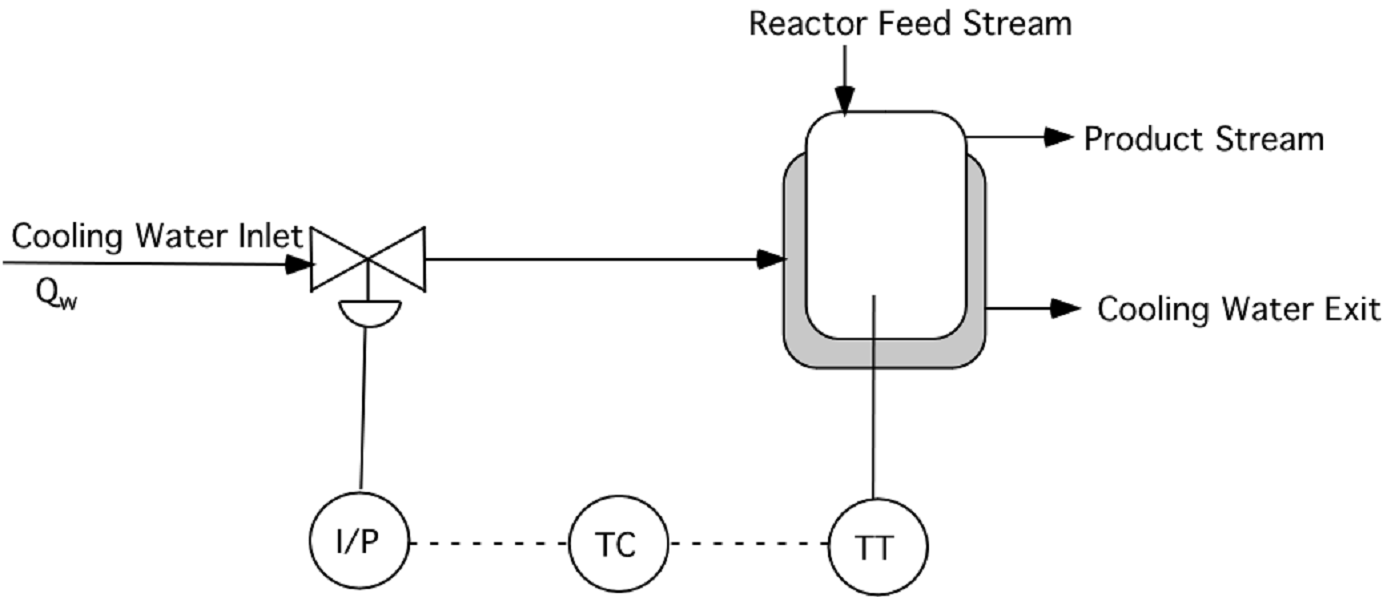

Cooling water flows through a jacket to control the temperature of a reactor, as shown below. The transfer function relating the reactor temperature $T$ to the flow rate of cooling water through the jacket ($Q_w$) is


$$\frac{T(s)}{Q_w(s)} = \frac{-0.7}{(s+1)(2s-1)} \frac{^oF}{gpm}$$


where the time constants are in minutes. The valve on the cooling water inlet fails in the open position (air-to-close), and passes 360 gpm of water when completely open. You may assume that the pressure drop across the valve is constant, that valve dynamics are negligible, and that the valve is linear. The temperature transmitter has a range of 200-400 $^\circ \text{F}$ and requires about 0.5 minutes for a reading to reach its final value ($3\tau-5\tau$). The output from the transmitter is a 4-20 mA signal to the reverse-acting controller. The proportional-only controller outputs a current signal, which is converted to pressure in a standard I/P transducer (4-20 mA, 3-15 psig). Sketch a block diagram for the system and determine the transfer function for each of the blocks, including units.

The process is unstable, but stable operation can be achieved with the feedback control loop shown and a proportional-only controller. What range of values of $K_c$ (if any) will make this process stable?

Kc = 0.01;
a = 0.08*0.75*30*0.7;
num = [a*0.1*Kc,a*Kc];
den = [0.2,2.1,0.9,-1+1.26*Kc];
sys = tf(num, den);
step(sys, 100)

## Solutions

If the above solutions require additional explanation, review the following videos. While the solutions work in Python, the analytical solutions are analogous to these exercises.

### Problem 1

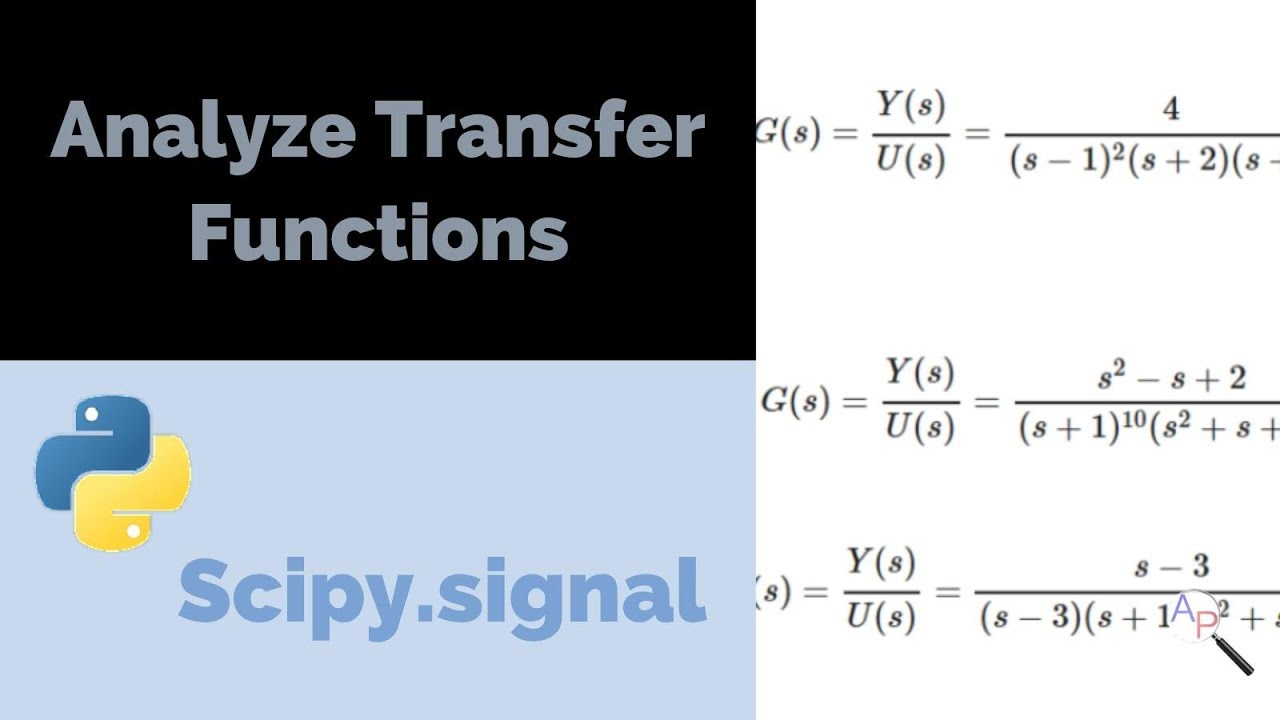

#### [View Solution Video](https://www.youtube.com/watch?v=24tc3f8Mju0)

### Problem 2

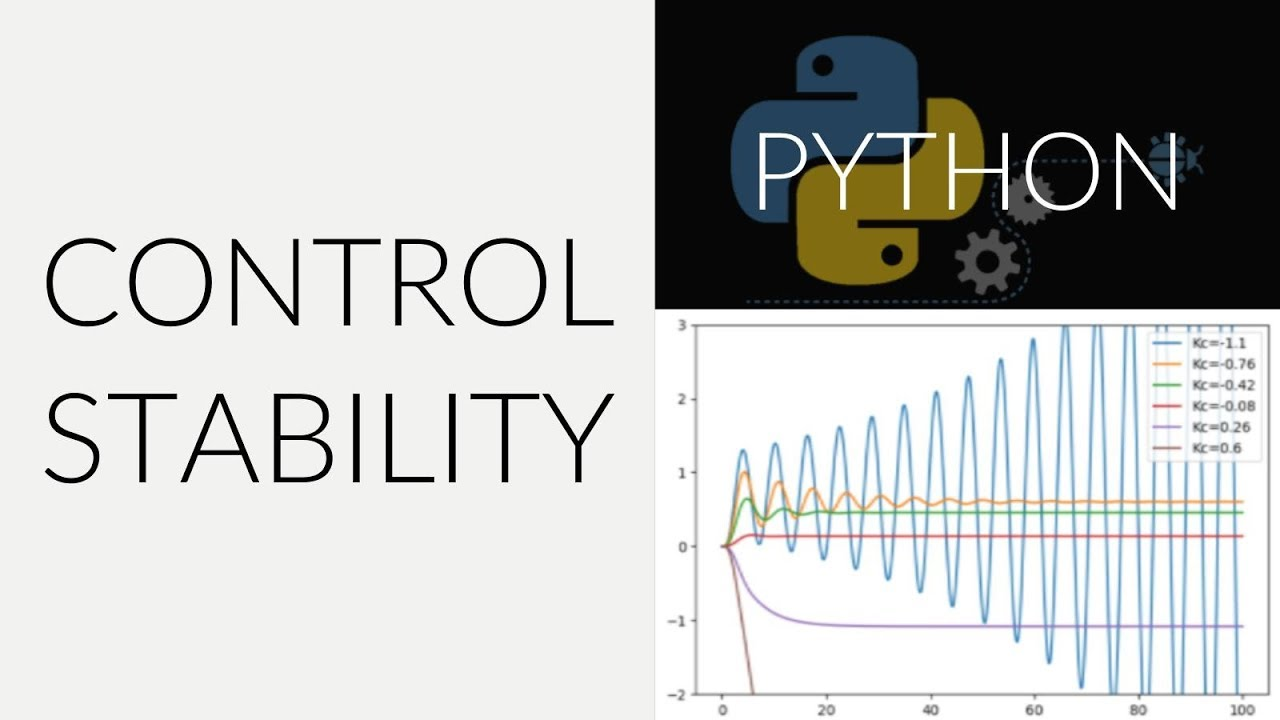

#### [View Solution Video](https://youtu.be/Y2BxAQxa0Vo)

### Problem 3

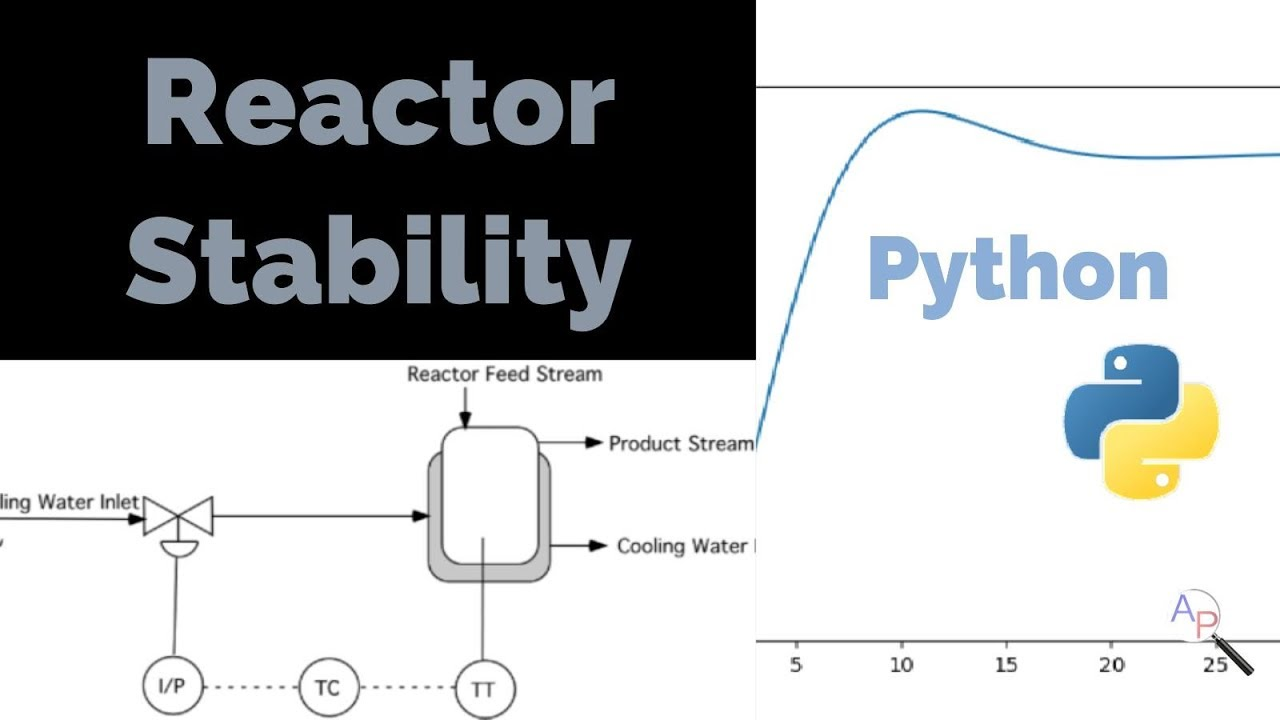

#### [View Solution Video](https://youtu.be/w0410EzTRf8)

function problem1a(disp)
if disp
    disp('STABILITY: Roots: 1, 1, -2, -3. Positive real roots indicate system is unstable')
    disp('OSCILLATION: Oscillation is caused by imaginary roots. No imaginary parts, no oscillation.')
    disp('FINAL VALUE: There is no final value as the FVT does not apply to unstable systems')
    
end
end

function problem1b(disp)
if disp
    disp('STABILITY: Roots: (-1)x10, -0.5 +or- 0.86i. No positive real roots, system is stable')
    disp('OSCILLATION: There are imaginary roots so the system oscillates')
    disp('FINAL VALUE: FVT = 2, which is equal to the gain.')
    disp('Use 1a as an example to simulate the system')
    
end
end

function problem1c(disp)
if disp
    disp('STABILITY: Roots: -1, -0.5 +or- 0.86i (3 is not a root since it cancels with the numerator). No positive real roots, system is stable')
    disp('OSCILLATION: There are imaginary roots so the system oscillates')
    disp('FINAL VALUE: FVT = 1, which is equal to the gain.')
    disp('Use 1a as an example to simulate the system')
    
end
end

function problem2(disp)
if disp
    disp('Kc < 0.5')
    
end
end

function problem3(disp)
if disp
    disp('0.79 < Kc < 8.29')
end
end